# NLS evolution a balanced star graph

Evolves a solution to the NLS equation on a "balanced" star graph as discussed in Kairzhan et al "Drift of Spectrally Stable Shifted States on Star Graphs," SIAM J. Appl. Dyn. Sys., 2018.

In this case, momentum is conserved if the initial conditions satisfy a certain matching condition.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you may choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

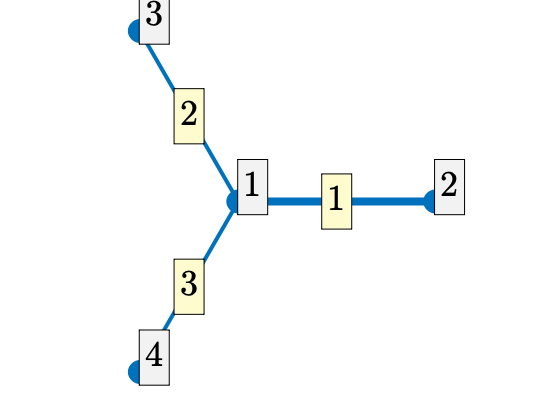

LVec = 8*pi;
weight = [2 1 1];
Phi = quantumGraphFromTemplate('star','LVec',LVec,'weight',weight);

%nX = 160;
%Phi = quantumGraphFromTemplate('star','LVec',LVec,'discretization','Chebyshev','nX',nX,'weight',weight);
Phi.plot('layout')

## Define and plot the initial conditions 

Define the cubic nonlinear Schrodinger time equation on Phi.

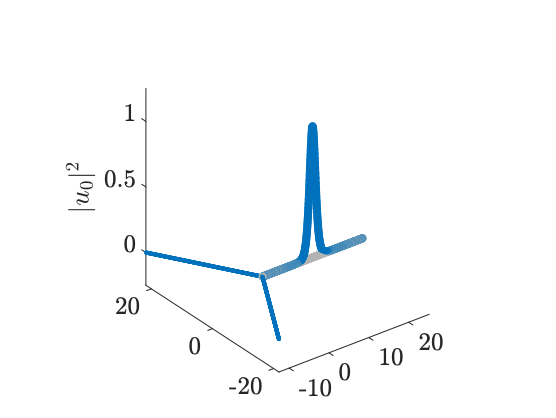

v0 = -1;     % Initial velocity
init1 = @(x) exp(-1i*x*v0).*sech(x-LVec/2);   
init2 = @(x)  exp(1i*x*v0).*sech(x+LVec/2);   
u0 = Phi.applyFunctionsToAllEdges({init1,init2,init2});
Phi.plot(abs(u0).^2);
zlabel('$|u_0|^2$')

## Function Definition and Time evolution


$$f(t,u) = \mu \triangle u + F(t,u)$$


mu = -1i; 
F =@(t,z) -2i * z.^2 .* conj(z);
tFinal = 11;
t=0:.5:tFinal; 
AbsTol=1e-6;
RelTol=1e-4;
tic
[t,u] = Phi.qgde23t(mu,F,t,u0,'AbsTol',AbsTol,'RelTol',RelTol);
toc

Elapsed time is 12.605623 seconds.


## Plotting the solution

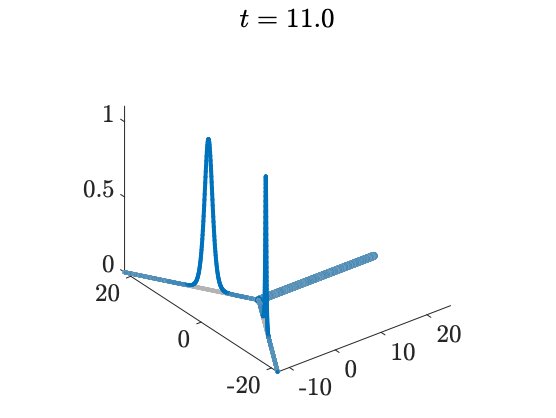

Phi.animatePDESolution(u,t);

## Error Analysis

Check for conservation of energy, mass and momentum.

nt = length(t);
energyVec = zeros(nt,1);
massVec = zeros(nt,1);
momentumVec= zeros(nt,1);

fcns.F=@(u)abs(u).^4; % The quartic term in the energy functional

for j=1:nt
    uj = u(:,j);
    energyVec(j)=Phi.energyNLS(uj,fcns);
    massVec(j) = Phi.norm(uj)^2;
    momentumVec(j) = Phi.momentumNLS(uj);
end

#### Plot the relative drift in the energy

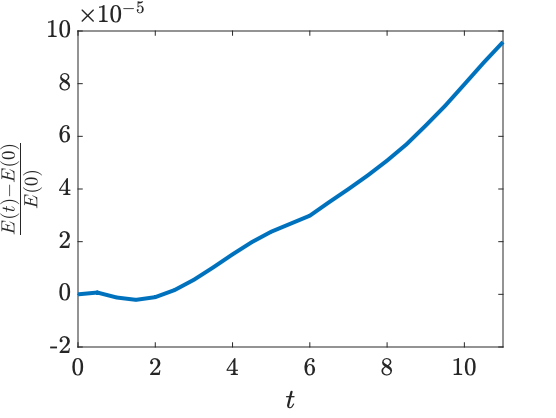

energyDiff=(energyVec-energyVec(1))/energyVec(1);
plot(t,energyDiff)
xlabel('$t$')
ylabel('$\frac{E(t)-E(0)}{E(0)}$')

#### Plot the relative drift in the mass

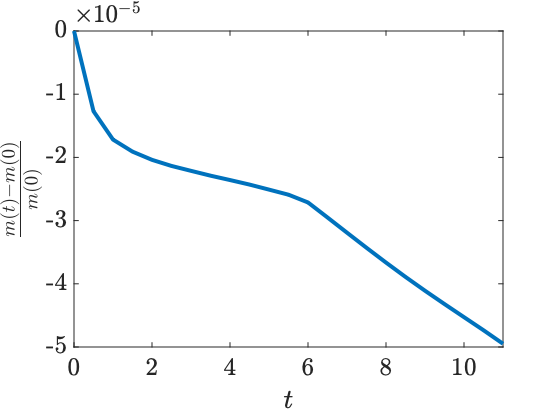

massDiff = (massVec-massVec(1))/massVec(1);
plot(t,massDiff)
xlabel('$t$')
ylabel('$\frac{m(t)-m(0)}{m(0)}$')

#### Plot the relative drift in the momentum

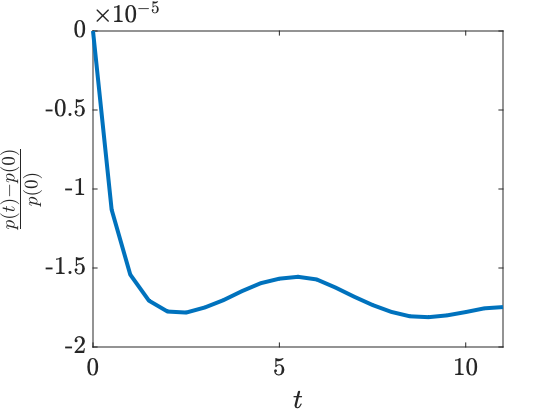

momentumDiff = (momentumVec-momentumVec(1))/momentumVec(1);
plot(t,momentumDiff)
xlabel('$t$')
ylabel('$\frac{p(t)-p(0)}{p(0)}$')